clear
clf
X = linspace(0,2*pi,500)';
R = randn(500,1);
Y = 0.5*(sin(2*pi*500*X)+ 2 * cos((R.*X)));
sequence = Y(275:335);


Adding noise to the original signal

mean_value = 0;
std = 5;  

% Set the number of samples and generate random noise
num_samples = 500;
rn = mean_value + std * randn(num_samples, 1);
Y = Y + rn;


ploting

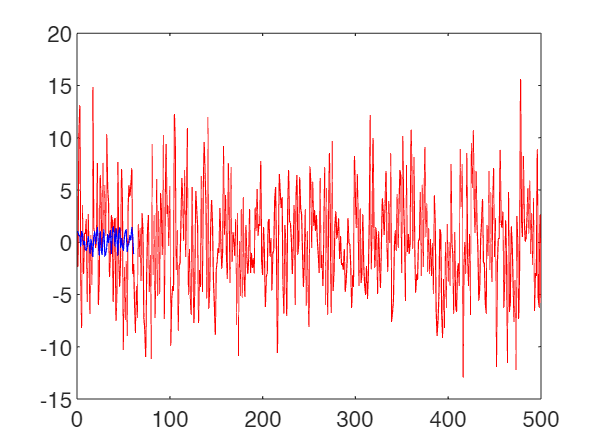


xlabel('x')
ylabel('y')

plot(Y, 'r');
hold on;
plot(sequence, 'b');
hold off;

Fin the match using xcross


[seq, lags] = xcorr(sequence, Y);
[match , idx]  = max(seq)

match = 95.0887

idx = 220

shift = -lags(idx)

shift = 280

Plot

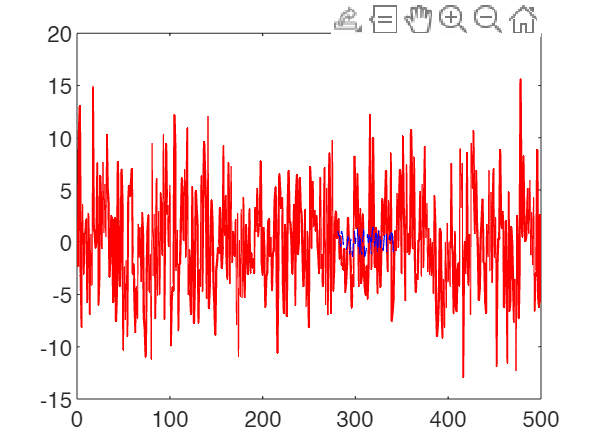

plot(Y, 'r', 'LineWidth', 1);
hold on;
plot(shift+1:shift + length(sequence), sequence, 'b-', 'LineWidth', 0.5, 'LineStyle', '--');
hold off;